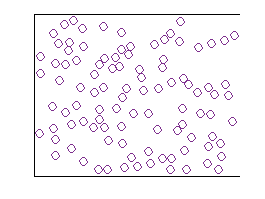

clear all

load('finalmat.mat')
load('positionmatrix.mat')
clf
for i=1:3
    x=walls(i,[1,3]);
    y=walls(i,[2,4]);
    plot(x,y,'k')
    set(gca,'XColor','none')
    axis off
    hold on
end

x=cell2mat(positionmatrix(:,1));
y=cell2mat(positionmatrix(:,2));

plot(x,y,'o')
hold off

load('results/finalmatwall0.6.mat')
n=100

n = 100

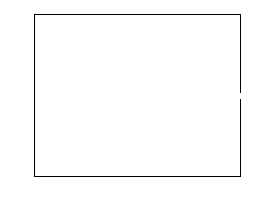

Index in position 1 exceeds array bounds.
Index must not exceed 72700.

for i=1:1:50000
% clf
for j=1:5
    x=walls(j,[1,3]);
    y=walls(j,[2,4]);
    
    plot(x,y,'k')
    set(gca,'XColor','none')
    axis off
    hold on
end
x=finalmat(n*i+(1:n),1);y=finalmat(n*i+(1:n),2);u=finalmat(n*i+(1:n),5);v=finalmat(n*i+(1:n),6);
plot(x,y,'o','MarkerSize',10)
title(finalmat(n*i+(1),7))
% quiver(x,y,u,v)
hold off

xlim([0,15])
ylim([0,15])
% hold all
pause(0.01);
end

% load('finalmat.mat')
% % finalmat([1:50]*200+i,1:2)
% 